# Signed Friedkin-Johnsen (SFJ)

Simulazione modello Signed Friedkin-Johnsen discreto su rete toy con $n=6$ agenti.


$$x\left(k+1\right)=\left(I-\Theta \right)Wx\left(k+1\right)+\Theta x\left(0\right)$$



$$P_w ={\left(I-\left(I-\Theta \right)W\right)}^{-1}$$


clear; clc; close all;

## 1. Definizione della rete

Il gafo diretto è definito attraverso dei nodi collegati da archi orientati dove i pesi sono gli elementi $a_{\mathrm{ij}}$ della adjacency matrix che vengono usati per definire la matrice di influenza $W$. 

Convenzione $w_{\mathrm{ij}\;}$: influenza dell'agente j sull'agente i.

n = 6;

weight_case = "Caso 1"; % nota: i pesi diagonali sono scelti per rispettare row-stochasticity w_ii = 1-sum(a_ij)

switch weight_case
    case "Caso 1"
        W = zeros(n);

        W(1,2) = 0.6;
        W(2,1) = 0.6; W(2,3) = 0.1;
        W(3,2) = 0.1; W(3,4) = -0.35; W(3,6) = 0.6;
        W(4,3) = 0.6; W(4,5) = 0.1; W(4,6) = -0.35;
        W(5,4) = 0.1;
        W(6,3) = -0.35; W(6,4) = 0.6;

        for i = 1:n
            W(i,i) = 1 - sum(W(i,:));
        end

        theta = [0.74; 0.80; 0.95; 0.95; 0.79; 0.55];
        case_name = "Caso 1";

    case "Caso 2"
        W = zeros(n);

        W(1,2) = 0.19;
        W(2,1) = 0.31; W(2,3) = 0.39;
        W(3,2) = 0.92; W(3,4) = -0.42; W(3,6) = 0.18;
        W(4,3) = 0.94; W(4,5) = 0.81; W(4,6) = -0.99;
        W(5,4) = 0.08;
        W(6,3) = -0.57; W(6,4) = 0.39;

        for i = 1:n
            W(i,i) = 1 - sum(W(i,:));
        end

        theta = [0.74; 0.80; 0.99; 0.99; 0.79; 0.55];
        case_name = "Caso 2";


    case "Caso 3"
        W = zeros(n);

        W(1,2) = -0.6;
        W(2,1) = -0.6; W(2,3) = -0.2;
        W(3,2) = -0.2; W(3,4) = 0.1; W(3,6) = 0.14;
        W(4,3) = -0.14; W(4,5) = 0.2; W(4,6) = 0.1;
        W(5,4) = 0.2;
        W(6,3) = -0.1; W(6,4) = -0.14;

        for i = 1:n
            W(i,i) = 1 - sum(W(i,:));
        end

        theta = [0.6; 0.6; 0.6; 0.2; 0.3; 0.5];
        case_name = "Caso 3";

    case "Caso 7"
        W = zeros(n);

        W(1,2) = 0.19;
        W(2,1) = 0.31; W(2,3) = 0.39;
        W(3,2) = 0.92; W(3,4) = -0.42; W(3,6) = 0.18;
        W(4,3) = 0.94; W(4,5) = 0.81; W(4,6) = -0.99;
        W(5,4) = 0.08;
        W(6,3) = -0.57; W(6,4) = 0.39;

        for i = 1:n
            W(i,i) = 1 - sum(W(i,:));
        end

        theta = [0; 0; 0; 0.8; 0.1; 0.3];
        case_name = "Caso 7";

    otherwise
        error('selezionare caso corretto');
end

disp("Selected case: " + case_name)

definiamo anche la matrice $\Omega$ per operare la gauge transformation

Omega = diag([1 -1 1 -1 -1 1]);
W = Omega * S * Omega;

## 2. Verifica condizioni

Impongo e verifico la row-stochasticity: per ogni riga la somma degli elementi deve essere 1.  

W(6,4) = 0.6;
W(6,6) = 1 - W(6,3) - W(6,4);

disp('Matrice signed W =');
disp(W);

%% 2. Verifica condizioni di base
rowSums = sum(W,2);
disp('Somma righe di W:');
disp(rowSums);

if all(abs(rowSums - 1) < 1e-12)
    disp('OK: W ha somma di riga pari a 1');
else

Matrice signed W =


    error('Le righe di W non sommano a 1');

    0.4000    0.6000         0         0         0         0
    0.6000    0.3000    0.1000         0         0         0
         0    0.1000    0.6500   -0.3500         0    0.6000
         0         0    0.6000    0.6500    0.1000   -0.3500
         0         0         0    0.1000    0.9000         0
         0         0   -0.3500    0.6000         0    0.7500



end

### calcolo verifica e plot autovalori:

Calcolo e verifico condizioni sugli autovalori e il raggio spettrale della matrice signed $W$.

nota: la gauge transformation lascia invariati gli autovalori nella trasformazione da W a S.

eigW = eig(W);
rhoW = max(abs(eigW));


Somma righe di W:


disp('Autovalori di W:');

     1
     1
     1
     1
     1
     1



disp(eigW);

disp(['Raggio spettrale rho(W) = ', num2str(rhoW)]);

figure('Color','w');
th = linspace(0, 2*pi, 400);

OK: W ha somma di riga pari a 1


plot(cos(th), sin(th), 'k--', 'LineWidth', 1.2); hold on;
plot(real(eigW), imag(eigW), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
axis equal; grid on;
xlabel('Parte reale');
ylabel('Parte immaginaria');
title('Autovalori di W nel piano complesso');
xlim([-1.2 1.2]);

Autovalori di W:


ylim([-1.2 1.2]);

  -0.2559 + 0.0000i
   0.5570 + 0.8147i
   0.5570 - 0.8147i
   1.0000 + 0.0000i
   0.8542 + 0.0000i
   0.9377 + 0.0000i



## 3. Parametri del modello SFJ

Definisco la matrice di stubbornness Theta, la condizione iniziale x0 e calcolo l'equilibrio teorico.

Theta = diag(theta);
D = eye(n) - Theta;

x0 = [-0.15045338; 0.46969690; -0.39592400; 0.38130010; -0.18239767; 0.49454417];
T = 25;

rhoDW = max(abs(eig(D*W)));
disp(['rho((I-Theta)W) = ', num2str(rhoDW)]);

PW = (eye(n) - D*W) \ Theta;
xStar = PW * x0;

disp('Equilibrio teorico x* =');
disp(xStar);

## 4. Simulazione del singolo SFJ

Qui eseguo la dinamica affine del signed FJ per una singola discussione.

Raggio spettrale rho(W) = 1


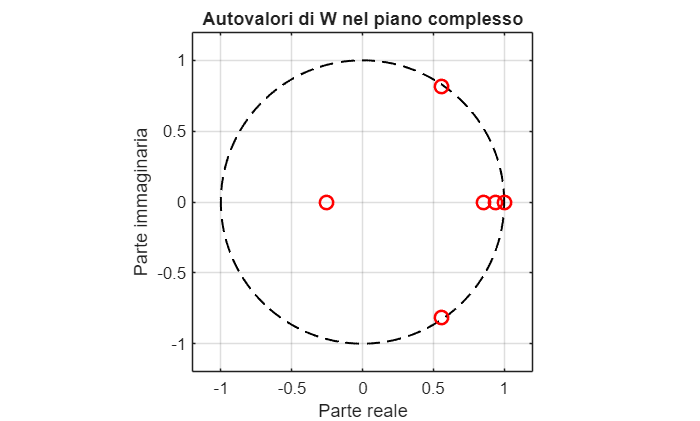

%% 4. Simulazione del singolo SFJ
X = zeros(n, T+1);
X(:,1) = x0;

for k = 1:T
    X(:,k+1) = D * W * X(:,k) + Theta * x0;
end

disp('Opinioni finali al termine della simulazione:');

disp(X(:,end));

disp('Opinioni finali al termine della simulazione:');
disp(X(:,end));

## 5. Simulazione concatenata

Riutilizzo la matrice P_W per mostrare l'evoluzione tra discussioni concatenate.

%% 5. Simulazione concatenata delle discussioni
% x(s,inf) = P_W x(s-1,inf)
Sdisc = 120;
Xdisc = zeros(n, Sdisc+1);
Xdisc(:,1) = x0;

for s = 1:Sdisc
    Xdisc(:,s+1) = PW * Xdisc(:,s);
end

disp('Opinioni dopo molte discussioni concatenate:');
disp(Xdisc(:,end));

disp(['rho(PW) = ', num2str(max(abs(eig(PW))))]);

## 6. Plot

Grafico del grafo signed, heatmap, traiettorie del singolo SFJ, traiettorie concatenate e numerical range.

%% 6. Plot del grafo signed
W_noLoops = W - diag(diag(W));
G = digraph(abs(W_noLoops') > 0);

xpos = [4.2 2.7 1.6 2.5 0.5 5.8];
ypos = [4.3 4.3 2.8 1.5 1.5 2.8];

figure('Color','w');
p = plot(G, 'XData', xpos, 'YData', ypos,'NodeColor', 'k', 'MarkerSize', 8, 'LineWidth', 1.8, 'ArrowSize', 12);
title('Struttura della rete signed', 'FontSize', 15, 'FontWeight', 'bold');
axis off;
p.NodeLabel = arrayfun(@num2str, 1:n, 'UniformOutput', false);
p.NodeFontSize = 12;

E = G.Edges.EndNodes;
numEdges = size(E,1);
edgeVals = zeros(numEdges,1);

for k = 1:numEdges
    src = E(k,1);
    dst = E(k,2);


Opinioni finali al termine della simulazione:


   -0.0573
    0.3845
   -0.3732
    0.3503
   -0.1686
    0.6421



Opinioni dopo molte discussioni concatenate:


    0.0447
    0.0431
    0.0200
    0.0185
    0.0105
    0.0161



rho(PW) = 1


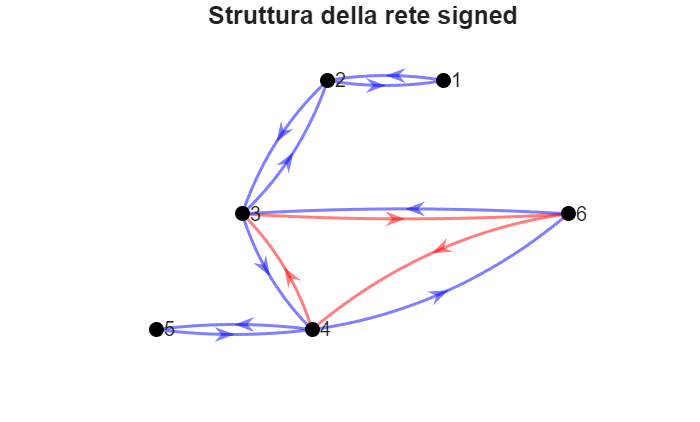

    % G = digraph(abs(W'')) quindi src->dst corrisponde a W(dst,src)
    if W_noLoops(dst,src) > 0
        edgeVals(k) = 1;   % positivo -> blu
    else
        edgeVals(k) = -1;  % negativo -> rosso
    end
end

p.EdgeCData = edgeVals;
p.EdgeColor = 'flat';
colormap([1 0 0; 0 0 1]);
caxis([-1 1]);

%% 7. Heatmap di W e di PW
figure('Color','w');
imagesc(W);
colorbar;
axis equal tight;
xlabel('j'); ylabel('i');
title('Matrice signed W');

figure('Color','w');
imagesc(PW);
colorbar;
axis equal tight;
xlabel('j'); ylabel('i');
title('Matrice P_W = (I-(I-Theta)W)^{-1}Theta');

%% 8. Traiettorie del singolo SFJ
figure('Color','w'); hold on;
for i = 1:n
    plot(0:T, X(i,:), 'LineWidth', 1.6);
    plot([0 T], [xStar(i) xStar(i)], '--', 'LineWidth', 0.9);

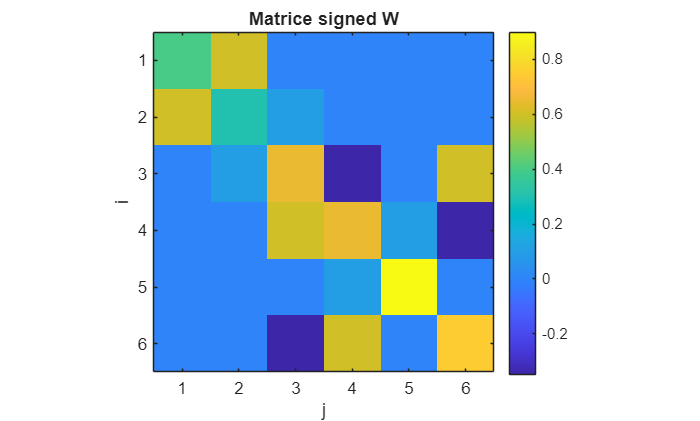

end

xline(0, ':k');
minHull = min(x0);
maxHull = max(x0);
plot([0 T], [minHull minHull], 'k:', 'LineWidth', 1.0);
plot([0 T], [maxHull maxHull], 'k:', 'LineWidth', 1.0);


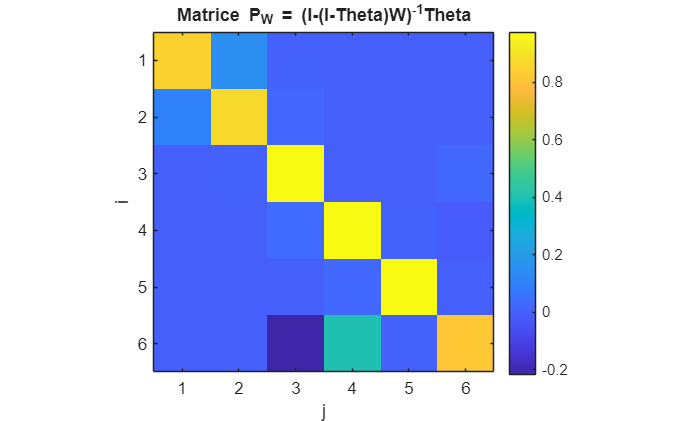

xlabel('Tempo k');
ylabel('Opinione');
title('Signed Friedkin-Johnsen: singola discussione');
legend('Agent 1','x_1^*','Agent 2','x_2^*','Agent 3','x_3^*', ...
       'Agent 4','x_4^*','Agent 5','x_5^*','Agent 6','x_6^*', ...
       'Location','eastoutside');
grid on;

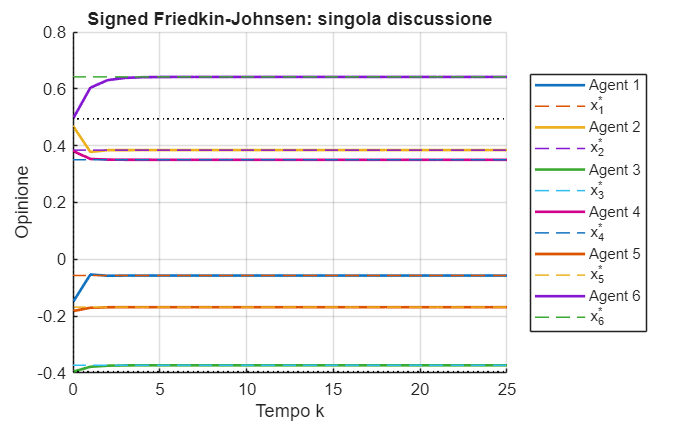


%% 9. Traiettorie del modello concatenato
figure('Color','w'); hold on;
for i = 1:n
        plot(0:Sdisc, Xdisc(i,:), 'LineWidth', 1.6);
end

xlabel('Discussione s');
ylabel('Opinione finale della discussione');
title('Concatenated signed FJ');
legend('Agent 1','Agent 2','Agent 3','Agent 4','Agent 5','Agent 6', ...
       'Location','eastoutside');
grid on;

Znr = numerical_range_boundary(W, 800);

figure('Color','w'); hold on;
fill(real(Znr), imag(Znr), [0.95 0.1 0.1], ...
    'FaceAlpha', 1.0, 'EdgeColor', 'k', 'LineWidth', 1.0);
plot(real(eigW), imag(eigW), 'k.', 'MarkerSize', 18);
plot(cos(th), sin(th), 'k--', 'LineWidth', 1.3);

axis equal; grid on; box on;
xlabel('Asse reale');
ylabel('Asse immaginario');
title('Numerical range \omega(W)');
xlim([-1.2 1.2]);
ylim([-1.2 1.2]);
set(gca, 'FontSize', 12);

%% 11. Informazioni finali utili
fprintf('\n--- CHECK RAPIDI ---\n');
fprintf('max x(0)      = %.4f\n', max(x0));
fprintf('min x(0)      = %.4f\n', min(x0));
fprintf('max x(T)      = %.4f\n', max(X(:,end))); 
fprintf('min x(T)      = %.4f\n', min(X(:,end))); 
fprintf('rho((I-Theta)W) = %.4f\n', rhoDW);
fprintf('rho(PW)         = %.4f\n', max(abs(eig(PW))));

## Funzione aggiuntiva

Funzione locale per il bordo del numerical range.

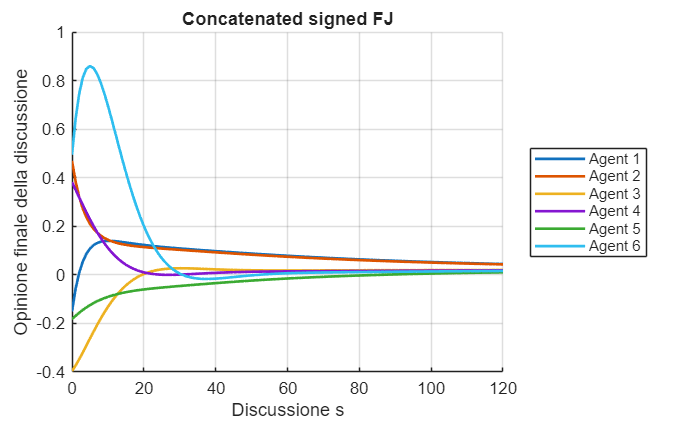

function Z = numerical_range_boundary(Q, Ntheta)
% Restituisce punti sul bordo del numerical range di Q usando la massimizzazione della parte reale della matrice ruotata.

    if nargin < 2
        Ntheta = 400;
    end

    theta = linspace(0, 2*pi, Ntheta+1);
    theta(end) = [];
    Z = zeros(Ntheta,1);

    for k = 1:Ntheta
        ang = theta(k);
        Hang = (exp(-1i*ang)*Q + exp(1i*ang)*Q')/2;

        [V,Daux] = eig(Hang);
        [~,idx] = max(real(diag(Daux)));
        v = V(:,idx);
        v = v / norm(v);

        Z(k) = v' * Q * v;
    end
end